clc; clear; close all;

syms l g B_p m_p theta(t) phi theta_0 t
thetaDot = diff(theta, t);
thetaDotDot = diff(thetaDot, t);

%m = l/g
%c = B_p/(g*m_p*l)
%k = 1
m = m_p*l^2

$$m = l^{2}\,m_{p}$$

c = B_p

$$c = B_{p}$$

k = m_p*g*l

$$k = g\,l\,m_{p}$$



%Roots
s1 = -c/(2*m)+sqrt(((c/(2*m)))^2-(k/m))

$$s1 = \sqrt{\frac{{B_{p}}^{2}}{4\,l^{4}\,{m_{p}}^{2}}-\frac{g}{l}}-\frac{B_{p}}{2\,l^{2}\,m_{p}}$$

s2 = -c/(2*m)-sqrt(((c/(2*m)))^2-(k/m))

$$s2 = -\sqrt{\frac{{B_{p}}^{2}}{4\,l^{4}\,{m_{p}}^{2}}-\frac{g}{l}}-\frac{B_{p}}{2\,l^{2}\,m_{p}}$$


wn = sqrt(k/m)

$$wn = \sqrt{\frac{g}{l}}$$

zeta = ((c/(2*m*wn)))

$$zeta = \frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}$$



s11 = (-zeta + 1i*sqrt(1-zeta^2))*wn

$$s11 = \left(-\frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}+\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\,\mathrm{i}\right)\,\sqrt{\frac{g}{l}}$$

s22 = (-zeta - 1i*sqrt(1-zeta^2))*wn

$$s22 = -\left(\frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}+\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\,\mathrm{i}\right)\,\sqrt{\frac{g}{l}}$$


test1 = vpa(subs(s1, [l g B_p m_p], [3 9.81 0.1 4.4]), 3)

$$test1 = -0.00126+1.81\,\mathrm{i}$$

test2 = vpa(subs(s11, [l g B_p m_p], [3 9.81 0.1 4.4]), 3)

$$test2 = -0.00126+1.81\,\mathrm{i}$$




ang = theta_0*exp(-zeta*wn*t)*cos(sqrt(1-zeta^2)*wn*t-phi)

$$ang = \theta_{0}\,\cos\left(\varphi -t\,\sqrt{\frac{g}{l}}\,\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\right)\,{\mathrm{e}}^{-\frac{B_{p}\,t}{2\,l^{2}\,m_{p}}}$$

ang = subs(ang,[l g B_p m_p phi theta_0], [1 9.81 1 5 0 0.2])

$$ang = \frac{{\mathrm{e}}^{-\frac{t}{10}}\,\cos\left(\frac{\sqrt{980}\,t}{10}\right)}{5}$$

%fplot(ang, [0 60])
%hold on
f = subs(0.2*exp(-zeta*wn*t),[l g B_p m_p phi theta_0], [1 9.81 1 5 0 0.2])

$$f = \frac{{\mathrm{e}}^{-\frac{t}{10}}}{5}$$

%fplot(f, [0 60])
%fplot(-f, [0 60])


Create sexy plotts

Plotting paramters 

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

Plotting 

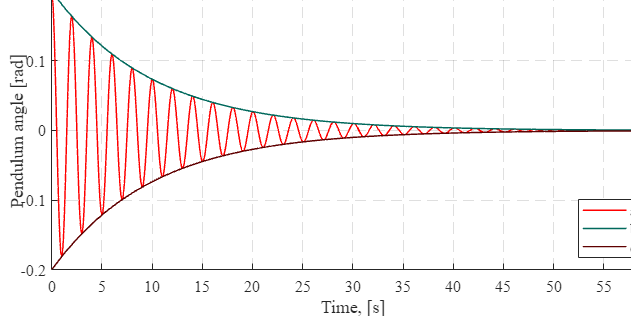

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame

hold on
plt1 = fplot(ang, [0 60]);
plt1.Color = 'r' ;   % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-';% '-', '--', ':', '-.'
%plt1.LineStyleMode = "manual"
plt1.LineWidth  = LW1;

plt2 = fplot(f, [0 60]);
plt2.Color = '#00695c';
plt2.LineStyle = '-';
plt2.LineWidth = LW1;

plt3 = fplot(-f, [0 60]);
plt3.Color = '#5f0000';
plt3.LineWidth = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:5:60];                    % Divisions on axes
ax.YTick = [-.5:.1:.5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

xaxis([ax.XTick(1) ax.XTick(end)]);

%leg = legend('Test data', 'i = k*U*(1-exp(1/tau*t)) ');
%leg = legend('Test data', '$i(t) = k \cdot U(t) \cdot (1-e^{-\frac{1}{\tau}t})$','Interpreter','latex')
leg = legend('a', 'b','c');
leg.Location = "southeast";

hold off
grid on
box on

div

a = vpa(isolate(zeta*wn==-0.1258, B_p), 4)

$$a = B_{p}=-0.2516\,l^{2}\,m_{p}$$

b = zeta*wn

$$b = \frac{B_{p}}{2\,l^{2}\,m_{p}}$$